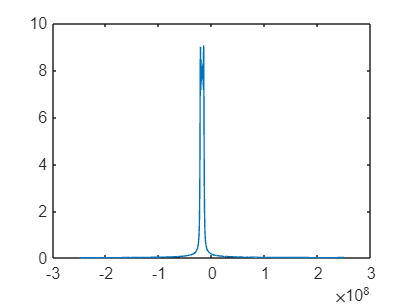

clear
clc

fs = 5e8;
f0 = (rand()*21+2)*1e6; %f0 in [2e6,23e6]Hz
f1 = (rand()*21+2)*1e6; %f1 in [2e6,23e6]Hz
B = f1 - f0;
T = (rand()*10+5)*(1e-6); %持续时间5~15us
% t_tmp = 0:1/fs:T;
chrp = my_chirp(T,f0,f1,fs); %生成chirp信号
% t0 = rand()*(1e-5); %开始时间0~10us
% n0 = floor(t0 * fs) + 1; %计算开始时间采样点序号
% n1 = n0 + length(chrp)-1;
real_fm = B/T;

% t = 0:1/fs:(26e-6); %时间序列 26us
% x = zeros(1,length(t));
% x(n0:n1) = x(n0:n1)+chrp;
% x = awgn(x,20);
% plot(real(x));
% stft(x,fs,"Window",hann(40,'periodic'));

% [pafmag,delay,doppler] = pambgfun(x,fs);
% [pafmag_chrp,delay_chrp,doppler_chrp] = pambgfun(chrp,fs);
% coef_chrp = -doppler_chrp(ceil(length(doppler_chrp)/2))*fs;
% coef = -doppler(ceil(length(doppler)/2))*fs;
% % imagesc(delay,doppler,pafmag)
% % axis xy
% % xlabel('Delay (sec)')
% % ylabel('Doppler Shift (Hz)')
% % colorbar
% 
% theta = 1:0.5:179;
% [R,xp] = radon(pafmag,theta);
% [R_chrp,xp_chrp] = radon(pafmag_chrp,theta);
% % imshow(R,[],'Xdata',theta,'Ydata',xp,'InitialMagnification','fit')
% % xlabel('\theta (degrees)')
% % ylabel('x''')
% % colormap(gca,hot), colorbar
% row_index = ceil(length(xp)/2);
% mag_af = R(row_index,:);
% indmax=find(diff(sign(diff(mag_af)))<0)+1;
% ind_candidate = indmax(mag_af(indmax)>250);
% ang = 90-theta(ind_candidate);
% fm = coef*tan(ang/180*pi);
% 
% row_index_chrp = ceil(length(xp_chrp)/2);
% mag_af_chrp = R_chrp(row_index_chrp,:);
% indmax_chrp = find(diff(sign(diff(mag_af_chrp)))<0)+1;
% ind_candidate_chrp = indmax_chrp(mag_af_chrp(indmax_chrp)>250);
% ang_chrp = 90 - theta(ind_candidate_chrp);
% fm_chrp = coef_chrp*tan(ang_chrp/180*pi);
% 
% a = acot(-fm/(fs^2))/(pi/2);
% y = myfrft(x',a)';
% u=linspace(-fs/2,fs/2-1,length(y));
% plot(u,abs(y));
% 
% a_chrp = 2/pi*acot(-fm_chrp/(fs^2));
% y_chrp = myfrft(chrp',a_chrp)';
% u_chrp=linspace(-fs/2,fs/2-1,length(y_chrp));
% plot(u_chrp,abs(y_chrp));

k_real = B/fs;
a_real = 2/pi*acot(-k_real);
y_real = myfrft(chrp',a_real)';
u_chrp=linspace(-fs/2,fs/2-1,length(chrp));
plot(u_chrp,abs(y_real));